# Try to develop set of ODEs

clear variables

addpath("~/ml-plot-utils/")

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end
plot_dir = 'plots';
if ~isfolder(plot_dir)
    mkdir(plot_dir)
end

## Description of system

The diagram and derivations below are based on:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

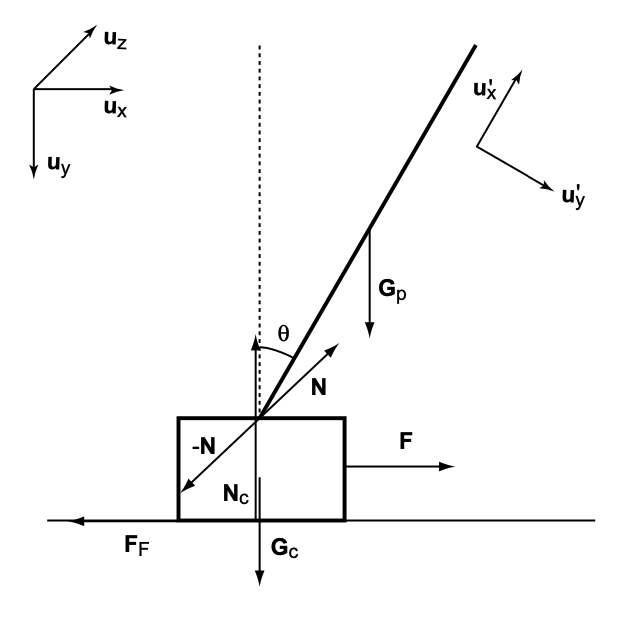

Note: Here, I will replace ${{\mathbf{u}}^{\prime } }_x$ and ${{\mathbf{u}}^{\prime } }_y$ with ${\mathbf{u}}_r$ and ${\mathbf{u}}_t$ to avoid confusion.

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of arm (clockwise from vertical up position) $\theta \left(t\right)$

- Angular velocity of cable$\dot{\;\theta \;} \left(t\right)$ (clockwise)

Other variables

- Upwards force on cart by track $N_c \left(t\right)$ (+ve upwards)

- Force exerted on arm by cart in x-direction $N_x \left(t\right)$ (+ve to right)

- Force exerted upwards on arm by cart (opposite to y-direction) $N_y \left(t\right)$ (+ve upwards)

- Frictional force exerted on cart by track $F_f \left(t\right)$ (+ve to left)

- Aerodynamic drag force on load opposite to x-direction $F_{d,x} \left(t\right)$(+ve to left)

- Aerodynamic drag force on load opposite to y-direction $F_{d,y\;} \left(t\right)$(+ve upwards)

Potential manipulatable input variables

- Horizontal driving force on cart $F\left(t\right)$

Potential disturbance input variables

- Horizontal wind velocity $v_{w,x} \left(t\right)$ - NOT YET IMPLEMENTED

Parameters

- Arm length $L$

- Cart mass $m_c$

- Pendulum mass $m_p$

- Acceleration due to gravity $g$

- Coefficient of friction for cart on track $\mu_c$

- Radius of the object at the end of the pole, $r$ (if it were a sphere)

- Aerodynamic drag coefficient of the object at the end of the pole $c_d$

- Mass density of air $\rho_a$

## Derivation of equations

% Define symbolic variables
syms x(t) theta(t) N_x(t) N_y(t) N_c(t) F_f(t) sgnNcDx sgnvx sgnvy
% Define symbolic constants
syms F L m_c m_p g muc r c_d rho

Co-ordinate systems:

    ${\mathbf{u}}_x ,{\mathbf{u}}_y$: unit vectors in the x direction (to the right), and y direction (down).

    ${\mathbf{u}}_r ={\mathbf{u}}_x \sin \theta -{\mathbf{u}}_y \cos \theta$: unit vector in direction of pole (radially outwards)

    ${\mathbf{u}}_t ={\mathbf{u}}_x \cos \theta +{\mathbf{u}}_y \sin \theta$: unit vector perpendicular to pole (clockwise tangential direction)

Force balance on cart (cartesian vectors):

    $\mathbf{F}+{\mathbf{F}}_f +{\mathbf{G}}_c -\mathbf{N}+{\mathbf{N}}_c =m_c {\mathbf{a}}_c$                                   (3)

where:

    $\mathbf{F}=F{\mathbf{u}}_x$: external force applied to cart (to the right)

    ${\mathbf{F}}_f =-F_f {\mathbf{u}}_x$: friction force on cart due to track (to the left when $F_f$ is +ve)

    ${\mathbf{G}}_c =m_c g{\mathbf{u}}_y$: downwards force due to weight of cart

    $\mathbf{N}=N_x {\mathbf{u}}_x -N_y {\mathbf{u}}_y$: force on pole due to cart (upwards and to right when $N_x$ and $N_y$ are +ve)

    ${\mathbf{N}}_c ={-N}_c {\mathbf{u}}_y$: Force on cart by track (upwards when $N_c$ is +ve)

    ${\mathbf{a}}_c =\ddot{x} {\mathbf{u}}_x$ : acceleration of cart

Decompose (3) into x, y directions:

    $F-F_f -N_x =m_c \ddot{x}$                                                    (4)

eqn4 = F - F_f(t) - N_x(t) == m_c * diff(x(t), t, t);

    $m_c g+N_y -N_c =0$                                                    (5)

eqn5 = N_c(t) == m_c * g + N_y(t)

$$eqn5 = N_{c}\left(t\right)=N_{y}\left(t\right)+g\,m_{c}$$

Coulomb friction model:

    $F_f =\mu_c |N_c |\textrm{sign}\left(\dot{x} \right)=\mu_c N_c \textrm{sign}\left(N_c \dot{x} \right)$                        (6)

% Friction force of track on cart (to the left when F_f(t) is positive)
% sgnNcDx represents sign(N_c * diff(x(t)))
eqn6 = F_f(t) == muc * N_c * sgnNcDx

$$eqn6(t) = F_{f}\left(t\right)=\mathrm{muc}\,\mathrm{sgnNcDx}\,N_{c}\left(t\right)$$

Force balance on pole (cartesian vectors):

    $\mathbf{N}+{\mathbf{F}}_d +{\mathbf{G}}_p =m_p {\mathbf{a}}_p$                                                         (7)

where:

    ${\mathbf{F}}_d =-F_{d,x} {\mathbf{u}}_x -F_{d,y} {\mathbf{u}}_y$ : Aerodynamic drag force on load (in opposite direction to velocity relative to air)

    ${\mathbf{G}}_p =m_p g{\mathbf{u}}_y$ : weight of load (downwards)

    ${\mathbf{a}}_p$ : acceleration of the load

Absolute magnitude of drag force on load:

    
$$F_d =\frac{1}{2}\rho {|\mathbf{v}|}^2 c_d A=\frac{1}{2}\rho c_d A\left({\left(v_x +v_{w,x} \right)}^2 +v_y^2 \right)$$


where

    $\mathbf{v}=\left(v_x +v_{w,x} \right){\mathbf{u}}_x +v_y {\mathbf{u}}_y$: velocity of the load through the air

and

    
$$\begin{array}{l}
v_x =\dot{x} +L\dot{\theta} \cos \theta \;\\
v_y =L\dot{\theta} \sin \theta 
\end{array}$$


% x and y components of velocity of load through the air
v_x = diff(x(t)) + L * diff(theta(t)) * cos(theta(t));
v_y = L * diff(theta(t)) * sin(theta(t));

Magnitudes of x and y components of drag force on load:


$$F_{d,x} =\frac{1}{2}\rho c_d Av_x^2 =\frac{1}{2}\rho c_d {A\left(\dot{x} +\dot{L} \sin \theta +L\dot{\theta} \cos \theta \right)}^2$$



$$F_{d,y} =\frac{1}{2}\rho c_d Av_y^2 =\frac{1}{2}\rho c_d {A\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2$$


% sgnvx, sgnvy represent sign(v_x(t)) and sign(v_y(t))
% TODO: Add wind as per above eqns
F_dx = sgnvx * 0.5 * rho * c_d * pi * r .^ 2  * v_x .^ 2;
F_dy = sgnvy * 0.5 * rho * c_d * pi * r .^ 2  * v_y .^ 2;

The acceleration of the load is due to the composed effects of:

- acceleration of cart

- rotation of pole with angular velocity $\omega =\dot{\theta} {\mathbf{u}}_z$

- angular acceleration of the pole $\varepsilon =\ddot{\theta} {\mathbf{u}}_z$

    ${\mathbf{a}}_p ={\mathbf{a}}_c +\varepsilon \times {\mathbf{r}}_p +\omega \times \left(\omega \times {\mathbf{r}}_p \right)$                            (8)

where:

    ${\mathbf{r}}_p =L\left(\sin \theta {\mathbf{u}}_y -\cos \theta {\mathbf{u}}_x \right)$ : position of centre of load relative to the pivot.

Substitute (8) into (7) and decompose into x and y directions:

    $N_x -F_{d,x} {\mathbf{u}}_x -F_{d,x} =m_p \left(\ddot{x} +L\ddot{\theta} \cos \theta -L{\dot{\theta} }^2 \sin \theta \right)$                    (11)

% Horizontal (x) component of force on pole by cart (+ve to right)
eqn11 = N_x - F_dx == m_p * ( ...
    diff(x(t), 2) ...
    + L * diff(theta(t), 2) * cos(theta(t)) ...
    - L * diff(theta(t))^2 * sin(theta(t)) ...
)

$$eqn11(t) = N_{x}\left(t\right)-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvx}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}=m_{p}\,\left(L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-L\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)$$

    $m_p g-F_{d,y} -N_y =m_p \left(L\ddot{\theta} \sin \theta +L{\dot{\theta} }^2 \cos \theta \right)$                (12)

% Vertical (y) component of force on pole by cart (upwards +ve)
eqn12 = N_y(t) == -F_dy + m_p * ( ...
    g ...
    - L * ( ...
        diff(theta(t), 2) * sin(theta(t)) ...
        + diff(theta(t))^2 * cos(theta(t)) ...
    ) ...
)

$$eqn12 = N_{y}\left(t\right)=m_{p}\,\left(g-L\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)\right)-1.5708\,L^{2}\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvy}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

Torque Balance of pole:

    
$$\mathbf{M}=\mathbf{I}\varepsilon +{\mathbf{r}}_p \times {\mathbf{a}}_c$$


where:

    $\mathbf{M}={\mathbf{r}}_p \times {\mathbf{G}}_p -{\mathbf{r}}_p \times {\mathbf{F}}_d$ : sum of non-inertial torques acting on the pole relative to the pivot.

    $\mathbf{I}=\frac{4}{3}m_p L^2$ : moment of inertia of the pole relative to the pivot

    ${\mathbf{r}}_p \times {\mathbf{a}}_c$ : torque generated by the inertial force caused by the acceleration of the cart.

Hence:

    
$$\left(m_p \mathrm{g}-F_{d,y} \right)\textrm{Lsin}\theta -F_{d,x} \textrm{Lcos}\theta =\frac{4}{3}m_p L^2 \ddot{\theta} +m_p \ddot{x} \textrm{Lcos}\theta$$


    $\left(m_p \mathrm{g}-F_{d,y} \right)\sin \theta -F_{d,x} \cos \theta =\frac{4}{3}m_p L\ddot{\theta} +m_p \ddot{x} \cos \theta$                (14)

% Angular acceleration
eqn14 = m_p * g * L * sin(theta(t)) == ...
    4 ./ 3 * m_p * L .^ 2 * diff(theta(t), 2) ...
    + m_p * diff(x(t), 2) * L * cos(theta(t))

$$eqn14 = L\,g\,m_{p}\,\sin\left(\theta \left(t\right)\right)=1.3333\,m_{p}\,L^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+m_{p}\,\cos\left(\theta \left(t\right)\right)\,L\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

From (4) and (11) we get:

$\ddot{x} =\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-F_f -F_{d,x} }{m_c +m_p }$                        (15)

% Horizontal acceleration of cart (+ve to right)
eqn15 = isolate(subs(eqn11, {N_x(t)}, ...
    {rhs(isolate(eqn4, N_x(t)))}), diff(x, t, t))

$$eqn15 = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F-F_{f}\left(t\right)+m_{p}\,\left(L\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvx}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}$$

% eqn15 = diff(x(t), 2) == ( ...
%     F ...
%     + m_p * L * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
%     - F_f(t) ...
% ) / (m_c + m_p)

By introducing this into Eq. 14 we get

eqn16 = isolate(subs(eqn14, {diff(x(t), 2)}, ...
    {rhs(eqn15)}), diff(theta(t), 2))

$$eqn16 = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{L\,g\,m_{p}\,\sin\left(\theta \left(t\right)\right)-\frac{L\,m_{p}\,\cos\left(\theta \left(t\right)\right)\,\left(F-F_{f}\left(t\right)+L\,m_{p}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvx}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{m_{c}+m_{p}}}{1.3333\,L^{2}\,m_{p}-\frac{L^{2}\,{m_{p}}^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}}$$

From Eq. 6, 5 and 12 we get

eqn17 = isolate(subs(eqn5, {N_y(t)}, {rhs(eqn12)}), N_c(t))

$$eqn17 = N_{c}\left(t\right)=g\,m_{c}+m_{p}\,\left(g-L\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)\right)-1.5708\,L^{2}\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvy}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

eqn18 = subs(eqn6, {N_c(t)}, {rhs(eqn17)})

$$eqn18(t) = F_{f}\left(t\right)=\mathrm{muc}\,\mathrm{sgnNcDx}\,\left(g\,m_{c}+m_{p}\,\left(g-L\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)\right)-1.5708\,L^{2}\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvy}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)$$

eqn21 = isolate(subs(eqn16, {F_f(t)}, {rhs(eqn18)}), diff(theta(t), t, t))

$$eqn21 = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{L\,g\,m_{p}\,\sin\left(\theta \left(t\right)\right)-\frac{L\,m_{p}\,\cos\left(\theta \left(t\right)\right)\,\left(F-\mathrm{muc}\,\mathrm{sgnNcDx}\,\left(g\,m_{c}+m_{p}\,\left(g-L\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}\right)-1.5708\,L^{2}\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvy}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{2}\right)+L\,m_{p}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvx}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{m_{c}+m_{p}}}{\left(\frac{L^{2}\,{m_{p}}^{2}\,\mathrm{muc}\,\mathrm{sgnNcDx}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{\left(m_{c}+m_{p}\right)\,\sigma_{1}}+1\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=1.3333\,L^{2}\,m_{p}-\frac{L^{2}\,{m_{p}}^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

eqn22 = subs(eqn15, {F_f(t)}, {rhs(eqn18)})

$$eqn22 = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F+m_{p}\,\left(L\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-L\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}\right)-\mathrm{muc}\,\mathrm{sgnNcDx}\,\left(g\,m_{c}+m_{p}\,\left(g-L\,\left(\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+\cos\left(\theta \left(t\right)\right)\,\sigma_{1}\right)\right)-1.5708\,L^{2}\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvy}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}\right)-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sgnvx}\,{\left(\frac{\partial }{\partial t}x\left(t\right)+L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

### Set parameter values

Define parameter values as struct

params = struct();
params.F = 10;
params.L = 5;
params.c_d = 0.47;  % drag coefficient of a sphere = 0.47
params.g = 9.8;
params.m_c = 5;
params.m_p = 2;
params.muc = 0.2;
params.r = 1;  % radius of load
params.rho = 1.293;  % density of air (kg/m3)

t = 0;
Y = [0 pi/2 53.9 0 0]';
crane_ODEs(t,Y,params)

ans =          0
         0
   53.9000
    1.4286
    1.4700
